# **Main script for "Inertial measurement units’ reliability for measuring knee joint angle during road cycling" research article**

In the following script VM denotes: virtual marker.

## Directory inclusion

Remember to include all the directories!

 
scrAddPath;

## Data import from the IMUs and the Qualisys motion tracking system

Meritve;
selectCandidate     = 7
selectMeasurement   = 2

scrUvozIMU;
scrQualisysUvoz;

 

## Shortening of the measurements 

**If the imported measurements already have the determined shortening parameters, the script wont execute!**

Most of the IMU measurements are longer than their optical counterparts, therefore, they need to be shortened.

The first figure that pops up, allows us to choose two timestamps for the gyroscope calibration, the second two for the measurement length, which is then used for all the IMU measurements.

Afterwards, a more zoomed in figure shows up, where you can fine tune the gyroscope offset calibration time stamps.

Finally, the next two figures, are only for the selection of the offset calibration timestamps for the other IMU sensor and its further fine tuning.

 
scrSkrajsevanjeMeritev;

## Simple calibration of the gyroscope and determination of the g vector

With the timestamps determined from the previous script, the gyroscopes for each IMU are calibrated, such that the gyroscopes while they are stationary, average out a reading of 0 deg/s.

Afterwards using the gyroscope readings, the rotation matrices are determined and the projections of the vector of gravitational acceleration are rotated using said matrices in the IMUs intrinsic coordinate frame.

 
scrKalibInOffset;

## Kalman filter

The filter used comes built in with the Matlab Sensor Fusion and Tracking toolbox. 

The implemented filter iteratively attempts to track errors in orientation, gyroscope output bias, and linear acceleration to output final orientation and angular velocity. For each iteration step, the filter first predicts orientation from the gyroscope readings, compensated for output bias and estimates the error in vector **g **projections, i.e., the difference between two calculated vectors **g**– one by considering the predicted orientation and the other by considering the acceleration measurements, having the linear acceleration estimated in the previous iteration step subtracted. Using this error, the Kalman filter parameters are updated according to the Kalman equations and used to finally correct the predicted orientation, gyroscope output bias and linear acceleration.

To adjust the filter parameters simply open the script below with the right click of the mouse.

 
scrKalmanFilter;

## **Exclusively run the next script if you need to determine the connecting rotation matrix for better alignment of the IMU and Qualisys !**

**The script wont run if you have selected a measurement session. Therefore, you need to proceed to the next session. **

**If you, however, need to determine the connecting rotation matrix for alignment, after choosing to save the best result please go back to the beginning of the script and select a measurement session to which the computed connecting rotation matrix applies to.**

saveLocation = "data/Meritve/RotationMatrixAlignment/Za kandidate >= 6/RotMat.mat"

Save current rotation matrices to external file?

connSave = false
 
scrConnectingRotMatrix;

## Calculating the joint angle using just the simple offset deduction method, and the alignment of all the computer angle signals for further evaluation afterwards

 
scrDolKotov;

## Evaluation of the joint angles

The script calculates the RMSE through the entire measurement and by each period for both joint angles and with respect to the optical motion tracking system with and without the VM.

Afterwards both of these calculations are plotted on the same graph.

The results are then stored for the metadata, saved in the script below.

Afterwards, the mean of the minimum and maximum joint angles is determined along with an interval of +- two standard deviations along with the average cadence of the cyclist.

 
scrRMSE;

## **Save into metadata xlsx file **

**When satisfied with the results of the previous script save the results into the xlsx file for metadata**

Remember to rename the filename variable so that the correct xlsx file is updated:

filename = "data/Meritve/Meritve.xlsx";

Afterwards, determine which data should be appended to the selected file: (Change the fields! the current xlsx file starts from 4 and upwards!)

When satisfied with the results insert the data:

scrExcellWrite;
 

## **RMSE plot of all the measurements **

Depending whether the measurement is 20min or 5 minutes long plots the RMSE by period for all measurements with a threshold determined as mean+2*std(mean). The passable values are then presented with the blue color, outliers are presented with the red color.

measurementType = 1

measurementType = 1

    2.5534

    2.0645

    4.7190

    5.3791



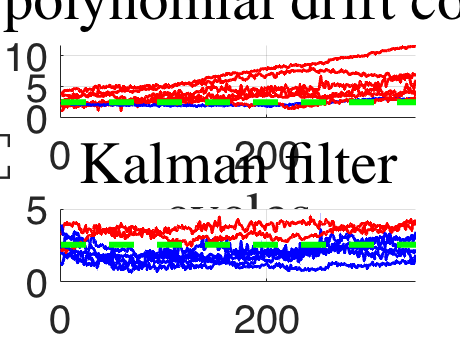

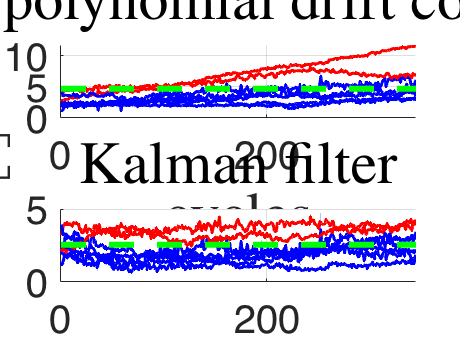

scrPlotRMSEThreshold;

## Plot of knee joint angle with respect to crank angle for both 5 and 20 minute measurements

scrPlotKneeCrankAngle;
 